## Load Data

% Sinusoid data
load('Isolated_Pendulum_swing.mat')
y = pendulum_angle.data;
N = size(t,2);
end_train = floor(N*1/2);

y = y(1:end_train);
t = t(1:end_train);
N = size(t,2);

clearvars -except y N t

## Apply PEM

theta0 = [-0.5 0 pi/2 0]';
theta = theta0;
lambda = 0.1;
maxiter = 500;
p = 4;
h = 0.01;

% initialize
converged = false;
maxiter_reached = false;
iter = 1;
while ~converged && ~maxiter_reached 

    %%%%%% YOUR CODE HERE %%%%%%

    [Abar,C,x0] = theta2matrices(theta, h);
    [yhat, xhat] = simsystem_y_as_vec(Abar, C, x0, N);
    E = y - yhat;
    psi = psi_fun(xhat, x0, Abar, h);
    N_E = length(E);
    J = 2/N_E * psi' * E; % Jacobian
    N_H = size(psi,1);
    H = 2/N_H * (psi' * psi); % Hessian

    invLM = (H + lambda * eye(p))\eye(p); %Levenberg-Marquardt singularity inverse
    theta_new = theta - invLM * J;

    
    % Check convergence
    if norm(theta_new - theta) < 1e-6
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end   


## Evaluate

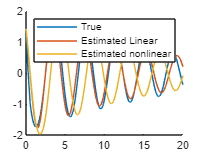

[yhat, xhat] = simsystem_y_as_vec(Abar, C, x0, N);
[yhatsin, xhatsin] = simsystem_y_as_vec_sin(Abar(:,1)-[1;0], Abar(:,2), C, x0, N);

figure;
hold on
plot(t,y);
plot(t,yhat);
plot(t,yhatsin);
legend('True', 'Estimated Linear', 'Estimated nonlinear')

## PEM (functions)

function [A,C,x0] = theta2matrices(theta, h)
% Converts theta into matrices for a full parameterisation with n = 3, l =
% 2
% Function INPUT
% theta     Parameter vector (vector of size: according to the realization)
%
% Function OUTPUT
% Abar      System matrix A (matrix of size n x n)
% Bbar      System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

%%%%%% YOUR CODE HERE %%%%%%
a1 = theta(1); a2 = theta(2);
x0 = theta(3:4);

A = [1 h; a1*h a2*h+1];
C = [1 0];
end

function psi = psi_fun(xhat, x0, Abar, h)
C = [1 0];

% Dimensions
n = 2; l = 1;

% Derivative Definitions
dAbar1 = [0 0; h 0];
dAbar2 = [0 0; 0 h];

dx03 = [1; 0];
dx04 = [0; 1];  

N = size(xhat,1); 
p = 4; % 11 sub-parameters of theta
xhat = xhat'; % x coming in is Nxn, now is nxN

dy = zeros(l,p);
psi = zeros((N-1)*l,p);

% First iteration
dx1 = dAbar1 * x0; dx2 = dAbar2 * x0;

dx=[dx1 dx2 dx03 dx04];
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = C * dx(:,i);
    end
    psi((k-l)*l+1:(k-l)*l+l,:) = -dy; % psi is relative to -dyhat

    % dx update
    % A parameters
    dx(:,1) = Abar * dx(:,1) + dAbar1 * xhat(:,k);
    dx(:,2) = Abar * dx(:,2) + dAbar2 * xhat(:,k);

    % x0 parameters
    dx(:,3) = Abar * dx(:,3);
    dx(:,4) = Abar * dx(:,4);

end
% psi = [zeros(2,p) ; psi]; % How to deal with dyhat0?
end

function [y,x] = simsystem_y_as_vec(A, C, x0, N)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% C system matrix (matrix of size l x n)
% x0 initial state (vector of size n x one)
%
% Function OUTPUT
% x state of system (vector of size N x n)
% y system output (matrix of size N x l)

% YOUR CODE HERE

n = length(x0);
l = size(C,1);
x = zeros(n, N);
y = zeros(l*N,1);
    
x(:,1) = x0;
y(1:2) = C * x(:,1);

for k = 2:N
    x(:,k) = A * x(:,k-1);
    y((k-1)*l+1:k*l) = C * x(:,k);
end

x = x';
end
function [A1, A2, C,x0] = theta2matrices_sin(theta, h)
% Converts theta into matrices for a full parameterisation with n = 3, l =
% 2
% Function INPUT
% theta     Parameter vector (vector of size: according to the realization)
%
% Function OUTPUT
% Abar      System matrix A (matrix of size n x n)
% Bbar      System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)

%%%%%% YOUR CODE HERE %%%%%%
a1 = theta(1); a2 = theta(2);
x0 = theta(3:4);

A1 = [1; a1*h]; A2 = [1*h; a2*h];
C = [1 0];
end

function psi = psi_fun_sin(xhat, x0, A1bar, A2bar, h)
C = [1 0];

% Dimensions
n = 2; l = 1;

x01 = x0(1); x02 = x0(2);

% Derivative Definitions
dA1bar1 = [0; h];
dA2bar2 = [0; h];

dx03 = [1; 0];
dx04 = [0; 1];  

N = size(xhat,1); 
p = 4; % 11 sub-parameters of theta
xhat = xhat'; % x coming in is Nxn, now is nxN

dy = zeros(l,p);
psi = zeros((N-1)*l,p);

% First iteration
dx1 = dA1bar1*sin(x01); dx2 = dA2bar2*x02;

dx=[dx1 dx2 dx03 dx04];
for k = 2:N % xhat is 0 - N-1, 
    % dy / psi update
    for i = 1 : p
        dy(:,i) = C * dx(:,i);
    end
    psi((k-l)*l+1:(k-l)*l+l,:) = -dy; % psi is relative to -dyhat

    % dx update
    % A parameters
    dx(:,1) = [(A1bar+[0;1]) A2bar] * dx(:,1) + dA1bar1 * sin(xhat(1,k));
    dx(:,2) = [(A1bar+[0;1]) A2bar] * dx(:,2) + dA2bar2 * xhat(2,k);

    % x0 parameters
    dx(:,3) = [(A1bar+[0;1]) A2bar] * dx(:,3);
    dx(:,4) = [(A1bar+[0;1]) A2bar] * dx(:,4);

end
% psi = [zeros(2,p) ; psi]; % How to deal with dyhat0?
end

function [y,x] = simsystem_y_as_vec_sin(A1, A2, C, x0, N)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
%
% Function INPUT
% A system matrix (matrix of size n x n)
% C system matrix (matrix of size l x n)
% x0 initial state (vector of size n x one)
%
% Function OUTPUT
% x state of system (vector of size N x n)
% y system output (matrix of size N x l)

% YOUR CODE HERE

n = length(x0);
l = size(C,1);
x = zeros(n, N);
y = zeros(l*N,1);
    
x(:,1) = x0;
y(1:2) = C * x(:,1);

for k = 2:N
    x(:,k) = A1 * sin(x(1,k-1)) + [1;0]* x(1,k-1) + A2 * x(2,k-1);
    y((k-1)*l+1:k*l) = C * x(:,k);
end

x = x';
end